# Capacity Factor and Fossil Detailed

Description: This algorithm calculates the capacity factor and the detailed composition of fossil fuels (share of coal, natural gas and oil)

Developed by Natanael Bolson

Supervised by Prof. Tad Patzek

Energy Geosystems Group -ANPERC - KAUST 11/2020

clc
clear
close all

## Load Data

load Data_EIA.mat

## Variables

% Electricity installed capacity (million kW)
El_Cap_Tot=Data_EIA.El_Cap_Tot(:,21:end);%[GW]
% nuclear electricity installed capacity (million kW)
El_Cap_Nuc=Data_EIA.El_Cap_Nuc(:,21:end);%[GW]
% fossil fuels electricity installed capacity (million kW)
El_Cap_Fos=Data_EIA.El_Cap_Fos(:,21:end);%[GW]
% renewable electricity installed capacity (million kW)
El_Cap_Ren=Data_EIA.El_Cap_Ren(:,21:end);%[GW]
% hydroelectricity installed capacity (million kW)
El_Cap_Hyd=Data_EIA.El_Cap_Hyd(:,21:end);%[GW]
% geothermal electricity installed capacity (million kW)
El_Cap_Geo=Data_EIA.El_Cap_Geo(:,21:end);%[GW]
% solar electricity installed capacity (million kW)
El_Cap_Sol=Data_EIA.El_Cap_Sol(:,21:end);%[GW]
% wind electricity installed capacity (million kW)
El_Cap_Win=Data_EIA.El_Cap_Win(:,21:end);%[GW]
% biomass and waste electricity installed capacity (million kW)
El_Cap_Bio=Data_EIA.El_Cap_Bio(:,21:end);%[GW]

% Electricity Generation
% electricity net generation (billion kWh)
El_Gen_Tot=Data_EIA.El_Gen_Tot(:,21:end);%[TWh]
% nuclear electricity net generation (billion kWh)
El_Gen_Nuc=Data_EIA.El_Gen_Nuc(:,21:end);%[TWh]
% fossil fuels electricity net generation (billion kWh)
El_Gen_Fos=Data_EIA.El_Gen_Fos(:,21:end);%[TWh
% renewable electricity net generation (billion kWh)
El_Gen_Ren=Data_EIA.El_Gen_Ren(:,21:end);%[TWh]
% hydroelectricity net generation (billion kWh)
El_Gen_Hyd=Data_EIA.El_Gen_Hyd(:,21:end);%[TWh]
% geothermal electricity net generation (billion kWh)
El_Gen_Geo=Data_EIA.El_Gen_Geo(:,21:end);%[TWh]
% solar electricity net generation (billion kWh)
El_Gen_Sol=Data_EIA.El_Gen_Sol(:,21:end);%[TWh]
% wind electricity net generation (billion kWh)
El_Gen_Win=Data_EIA.El_Gen_Win(:,21:end);%[TWh]
% biomass and waste electricity net generation (billion kWh)
El_Gen_Bio=Data_EIA.El_Gen_Bio(:,21:end);%[TWh]

% Electricity production from coal sources (% of total)
El_F_Coal=Data_EIA.El_F_Coal(:,21:end);
% Electricity production from natural gas sources (% of total)
El_F_Gas=Data_EIA.El_F_Gas(:,21:end);
% Electricity production from oil sources (% of total)
El_F_Oil=Data_EIA.El_F_Oil(:,21:end);
% 1980:2015

Year=2000:2017;

% Colormap
Color=[85,200,60       % Biomass 0,104,55  
      55,55,55          % Fossil
      202,0,32          % Geothermal
      33,102,172        % Hydro
      128,115,172        % Nuclear
      255,199,44      % Solar 244,109,67 
      146,197,222]/255; % Wind 

% From EIA
%Total World	Installed coal-fired generating capacity: [GW]
% 2010:2050 up tp 2017
W_El_Cap_Coal=[1593.6649	1672.3734	1742.8409	1802.5896...
	1876.973	1957.9339	2027.8577	2086.9423	2104.0165...
	2126.8143	2153.7694	2159.7448	2165.6024	2167.6395...
	2169.5158	2173.0731	2179.5206	2187.6071	2197.2746...
	2208.4714	2217.3036	2202.0152	2184.2036	2171.561...
	2156.0182	2143.3758	2134.6261	2124.7156	2115.9661...
	2107.2147	2098.4606	2096.8062	2096.3669	2095.3652...
	2094.927	2094.4912	2115.7467	2137.0039	2158.2602...
	2179.5166	2200.772];
%Total World	Installed liquids-fired generating capacity: 
W_El_Cap_Oil=[290.6505	295.3858	298.0867	303.1172	308.9278...
	309.1566	309.6275	353.6116	333.4196	315.0393 296.942...
	278.2492	264.1795	250.4885	235.4895	222.1089 211.8806...
	204.7907	197.4233	189.212	182.644	178.4611 174.7192	170.4113...
	166.2585	162.0866	159.1842	156.5818 153.7575	151.1551...
	148.5527	147.4493	146.1709	145.2895 144.4082	143.401	143.4877...
	143.5746	143.6614	143.7483 143.8351];
%Total World	Installed natural-gas-fired generating capacity: 
W_El_Cap_gas=[1359.7427	1403.1716	1451.6739	1485.3259	1551.6345...
	1578.6068	1582.8705	1631.9297	1643.8534	1650.8136	1661.7834...
	1680.6414	1692.3999	1706.9281	1725.0204	1744.9503	1795.1432...
	1847.168	1894.506	1940.8896	1992.7392	2065.4649	2142.4198...
	2216.6554	2293.9924	2364.9939	2410.1708	2458.613	2500.9513...
	2547.3938	2594.0358	2631.3688	2667.3042	2703.2581	2741.3491...
	2780.8447	2832.0197	2879.8347	2931.1013	2980.8333	3031.498];

## Capacity Factor Macro

% Fossil
CF_Fos=El_Gen_Fos(1,:)./(El_Cap_Fos(1,:)/1000*24*365);
% Nuclear
CF_Nuc=El_Gen_Nuc(1,:)./(El_Cap_Nuc(1,:)/1000*24*365);
% Renewables
CF_Ren=El_Gen_Ren(1,:)./(El_Cap_Ren(1,:)/1000*24*365);
% Total
CF_Tot=El_Gen_Tot(1,:)./(El_Cap_Tot(1,:)/1000*24*365);


## Detailed estimations for coal gas and oil

% Cross check less than 5% error
A= W_El_Cap_Coal(1:6)+W_El_Cap_gas(1:6)+W_El_Cap_Oil(1:6);
B=El_Cap_Fos(1,11:end-2);
A./B % ok

ans =     0.9652    0.9657    0.9704    0.9711    0.9724    0.9746


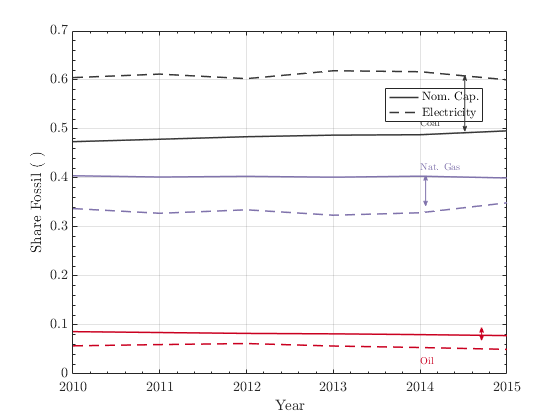

% Shares
Share_Coal=W_El_Cap_Coal(1:6)./El_Cap_Fos(1,11:end-2);
Share_Gas=W_El_Cap_gas(1:6)./El_Cap_Fos(1,11:end-2);
Share_Oil=W_El_Cap_Oil(1:6)./El_Cap_Fos(1,11:end-2);
% Electricity from Fossil
El_F_Tot=El_F_Coal(1,11:end)+El_F_Gas(1,11:end)+El_F_Oil(1,11:end);
Y_CF=2010:2015;% Year

figure('Name','Nominal capacity and electricity generation')
plot(Y_CF,Share_Coal,"Color",Color(2,:),'LineWidth',1.5)
hold on
plot(Y_CF,El_F_Coal(1,11:end)./El_F_Tot,'--',"Color",Color(2,:),'LineWidth',1.5)
plot(Y_CF,Share_Gas,"Color",Color(5,:),'LineWidth',1.5)
plot(Y_CF,El_F_Gas(1,11:end)./El_F_Tot,'--',"Color",Color(5,:),'LineWidth',1.5)
plot(Y_CF,Share_Oil,"Color",Color(3,:),'LineWidth',1.5)
plot(Y_CF,El_F_Oil(1,11:end)./El_F_Tot,'--',"Color",Color(3,:),'LineWidth',1.5) 
leg={'$$\mathrm{Nom.~Cap.}$$';'$$\mathrm{Electricity}$$'};
legend(leg,'Location','best','FontSize', 12,'NumColumns',1,'interpreter','latex')
xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Share~Fossil~(~)}$$','interpreter','latex')
box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

annotation('doublearrow',[0.86 0.86],[0.19 0.22],"Color",Color(3,:),'Head1Width',5,'Head2Width',5,'Head1Length',5,'Head2Length',5)
annotation('doublearrow',[0.76 0.76],[0.51 0.582],"Color",Color(5,:),'Head1Width',5,'Head2Width',5,'Head1Length',5,'Head2Length',5)
annotation('doublearrow',[0.83 0.83],[0.688 0.82],"Color",Color(2,:),'Head1Width',5,'Head2Width',5,'Head1Length',5,'Head2Length',5)
text(2014,0.025,'Oil','Interpreter','latex','Color',Color(3,:))
text(2014,0.42,'Nat. Gas','Interpreter','latex','Color',Color(5,:))
text(2014,0.51,'Coal','Interpreter','latex','Color',Color(2,:))

% print('-depsc2','-r400','Fos_Det_Share.eps');
% print('-dpng','-r400','Fos_Det_Share.png');

This gap can provide some insight on the role that the different power asources are playing. Coal is more as a base load, Natural gas has a role as a peak consumption supply. Oil has a role as peak demand and backup power (e.g., diesel generators).

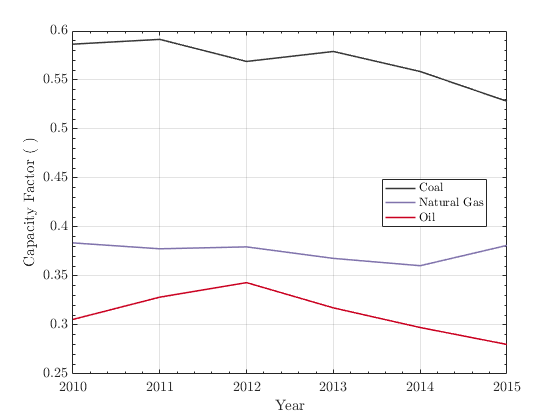

% Capacity Factor for 2010:2015
CF_Gas=El_F_Gas(1,11:end)/100.*El_Gen_Tot(1,11:end-2)*1000./(W_El_Cap_gas(1:6)*8760);
CF_Coal=El_F_Coal(1,11:end)/100.*El_Gen_Tot(1,11:end-2)*1000./(W_El_Cap_Coal(1:6)*8760);
CF_Oil=El_F_Oil(1,11:end)/100.*El_Gen_Tot(1,11:end-2)*1000./(W_El_Cap_Oil(1:6)*8760);
Y_CF=2010:2015;

figure('Name','Capacity Factor Oil Gas Coal')
plot(Y_CF,CF_Coal,"Color",Color(2,:),'LineWidth',1.5)
hold on
plot(Y_CF,CF_Gas,"Color",Color(5,:),'LineWidth',1.5)
plot(Y_CF,CF_Oil,"Color",Color(3,:),'LineWidth',1.5)
leg={'$$\mathrm{Coal}$$';'$$\mathrm{Natural~Gas}$$';'$$\mathrm{Oil}$$';};
legend(leg,'Location','best','FontSize', 12,'NumColumns',1,'interpreter','latex')
xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

% print('-depsc2','-r400','Fos_Det_CF.eps');
% print('-dpng','-r400','Fos_Det_CF.png');

## Capacity Factor Trend

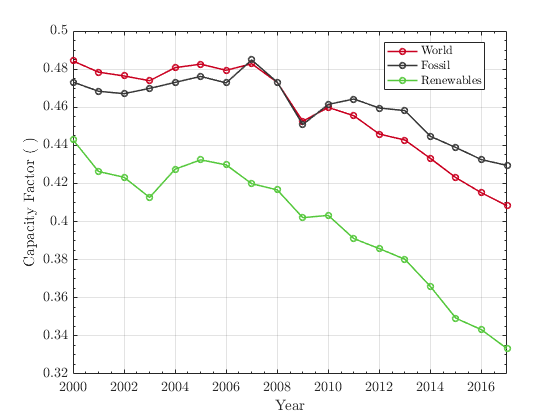

figure('Name','Capacity World and Renewables')
plot(Year,CF_Tot,'-o',"Color",Color(3,:),'LineWidth',1.5)
hold on
plot(Year,CF_Fos,'-o',"Color",[55 55 55]/255,'LineWidth',1.5)
plot(Year,CF_Ren,'-o',"Color",Color(1,:),'LineWidth',1.5)
leg={'$$\mathrm{World}$$';'$$\mathrm{Fossil}$$';'$$\mathrm{Renewables}$$';};
legend(leg,'Location','best','FontSize', 12,'NumColumns',1,'interpreter','latex')
xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
box on
grid on
xlim([2000 2017])
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

% print('-depsc2','-r400','CF_World_Ren.eps');
% print('-dpng','-r400','CF_World_Ren.png');

## Installed Nominal Capacity

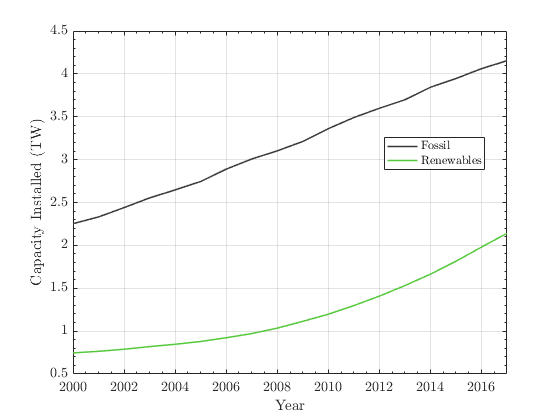

figure('Name','Capacity World and Renewables')
plot(Year,El_Cap_Fos(1,:)/1000,'-',"Color",[55 55 55]/255,'LineWidth',1.5)
hold on
plot(Year,El_Cap_Ren(1,:)/1000,'-',"Color",Color(1,:),'LineWidth',1.5)
leg={'$$\mathrm{Fossil}$$';'$$\mathrm{Renewables}$$';};
legend(leg,'Location','best','FontSize', 12,'NumColumns',1,'interpreter','latex')
xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Installed~(TW)}$$','interpreter','latex')
box on
grid on
xlim([2000 2017])
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

% print('-depsc2','-r400','Cap_Fos.eps');
% print('-dpng','-r400','Cap_Fos.png');